# Working with Textual Data 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Frequently, you may want to interact with a computer using text rather than numbers. There are several common rules for working with text on a computer that involve encodings such as ASCII, UTF-8, or Unicode that provide rules for translating between characters and numbers. Have you ever encountered a password field that disallowed characters such as % or + or even just blank spaces? This is also related to the prevalence of the English alphabet a-z and A-Z in computing because the standard textual encodings place that alphabet in the first few bytes. Another bit of excitement can come when characters that look identical to us, such as an English "a" or a Cyrillic "а," are encoded differently by computers (U+0061 versus U+0430). Phishing attacks can leverage this to create, for instance, a URL that looks correct to humans but is interpreted as obviously different by computers. 

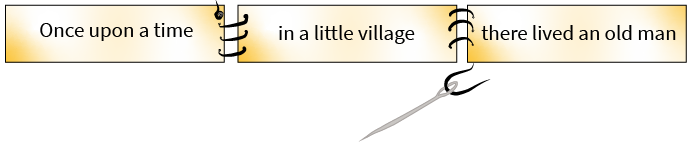

In this script, you will learn to define, edit, format, and string together textual data for a computer.  

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB. This script also assumes basic familiarity with strings, as discussed in the [Fundamentals of Programming](https://www.mathworks.com/matlabcentral/fileexchange/103225-fundamentals-of-programming) script.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.

## Recognizing Textual Data Types

The textual data types in MATLAB are *string* and *char*. The name `char` is a shortened form of "`character array`." As with the different [data types for numbers](matlab: edit NumericDataTypes.mlx), different textual data types may be interchangeable in some computations or languages and not in others. There can also be different amounts of memory required to store the same text as a string or as a character array. When you run the following code, you will assign three different representations of 7 to variables in MATLAB. The command `whos` will display information about the variables, including their name, their size, the amount of memory they take in bytes, and the data type. 

s = "7"

s = "7"

c = '7'

c = '7'

n = 7

n = 7

comb = s+c+n

comb = "777"

whos s c n comb

  Name      Size            Bytes  Class     Attributes

  c         1x1                 2  char                
  comb      1x1               150  string              
  n         1x1                 8  double              
  s         1x1               150  string              



The command `whos` displays information about the variables. The `Size` refers to the dimensions as an array, while `Bytes` tracks the amount of memory required and `Class` reports the data type. A `string` is a sequence of characters treated as a single unit, while a `char` is an array of length equal to the number of characters where each element of the array is a single character.

 **Reflect**.

- What is the syntax for defining a string in MATLAB?

- What is the syntax for defining a character array in MATLAB?

  **Try**.

- Replace lines 1-3 in the code above with 

             Rerun the code. What has changed? What stayed the same?

- Convert between datatypes with

            Rerun the code. What has changed? What has stayed the same?

### Further Explorations on Text Encoding

There are many possible ways to encode characters as numeric values. This can become quite complicated when several different character sets are included, such as the English alphabet, Korean Hangul syllables, currency symbols, and selected emojis. You may encounter terminology such as [UTF-8](https://en.wikipedia.org/wiki/UTF-8), [UTF-16](https://en.wikipedia.org/wiki/UTF-16), [UTF-32](https://en.wikipedia.org/wiki/UTF-32), [ASCII](https://www.mathworks.com/help/matlab/matlab_prog/unicode-and-ascii-values.html), or [Unicode](https://www.mathworks.com/help/matlab/matlab_prog/unicode-and-ascii-values.html), which specifies how text is encoded in your system.

## Concatenating Textual Data

  **Try**.

- Create a variable called `myName` containing your name as a string. Then run the code:

            by copying it into the code box below.

myName = "Emma";
greeting = s+c+myName

greeting = "77Emma"

When the operands are strings or chars, the `+` operator in MATLAB will concatenate into one object of a textual data type. 

- What happens if you concatenate two or more strings? 

- What happens if you concatenate two or more chars? 

- What happens if you concatenate a string and a double? 

strExample = "This is a string.";
charExample = 'This is a char.';
doubleExample = 3.9086517;

strExample + greeting

ans = "This is a string.77Emma"

c

c = '7'

charExample

charExample = 'This is a char.'

charExample + c

ans =    139   159   160   170    87   160   170    87   152    87   154   159   152   169   101


strExample + doubleExample

ans = "This is a string.3.9087"

 **Reflect**.

- Does the order of concatenation matter? 

- What happens with whitespace? What is the importance of whitespace in code? 

- Is there a reason that code is frequently written in a fixed-width font?

- How important is the precise use of language, including capitalization and punctuation, in code?

- How is code like prose? How is code unlike prose?

## Operating on Strings

### Formatting Strings for Consistency

  **Try**. Run this section, then change the value of `phrase` and rerun this section. 

phrase = "`Twas BRILLIG and the sLiThY toves..."

phrase = "`Twas BRILLIG and the sLiThY toves..."

upper(phrase)

ans = "`TWAS BRILLIG AND THE SLITHY TOVES..."

lower(phrase)

ans = "`twas brillig and the slithy toves..."

reverse(phrase)

ans = "...sevot YhTiLs eht dna GILLIRB sawT`"

out = split(phrase," ");
sort(out)

ans = 6×1 string array
    "BRILLIG"
    "`Twas"
    "and"
    "sLiThY"
    "the"
    "toves..."


out = split(lower(phrase)," ");
sort(out)

ans = 6×1 string array
    "`twas"
    "and"
    "brillig"
    "slithy"
    "the"
    "toves..."


 **Reflect**.

- Can you tell what the commands `upper`, `lower`, `reverse`, `split`, and `sort` do? Check the documentation on `sort` to see if you were correct.  

  **Try**. Sort `phrase` word by word in reverse alphabetical order.

% Solution
out = split(lower(phrase)," ");
sort(out,"descend")

ans = 6×1 string array
    "toves..."
    "the"
    "slithy"
    "brillig"
    "and"
    "`twas"


% End Solution

### Formatting Numeric Data as a String

You are likely to encounter situations where you want to present numeric data as a string, perhaps as human-readable output from a program, or to create a label for a plot. Using formatting commands to control how such a value is displayed can be helpful.  

#### Using `sprintf`

% Choosing the number of digits after the decimal place
A = sqrt(2)*ones(1,3);
txt = sprintf("Building up the square root of 2: \n| %.2f      |\n| %.3f     |\n| %.4f... |", A)

txt =     "Building up the square root of 2: 
     | 1.41      |
     | 1.414     |
     | 1.4142... |"


#### Using `compose`

% Embedding dynamic values into a string

options = ["SI" "US"];
chooseUnits = options(1);

% Using symbolic units, calculate the acceleration due to gravity
% on Earth in the chosen unit system
u = symunit;
g = 9.80665*u.m/(u.s)^2;
g = unitConvert(g,chooseUnits);
[g0,units] = separateUnits(g);
g0 = double(g0);

% Create string labels for the units in SI and US systems
unitStr = ["m/s^2" "ft/s^2"];
myUnitLabel = unitStr(chooseUnits==options);

% Build the format string and compose it with the calculated values
fmtStr = "A rough approximation of g is %.0f.\n" + ...
    "A standard approximation is %.3g %s, \n\tbut " + ...
    "the exact standard value of g0 is %f %s. \n" + ...
    "Exactly 5 decimal places of pi are %.5f.";
str = compose(fmtStr,[g0 g0 myUnitLabel g0 myUnitLabel pi])

str =     "A rough approximation of g is 10.
     A standard approximation is 9.81 m/s^2, 
     	but the exact standard value of g0 is 9.806600 m/s^2. 
     Exactly 5 decimal places of pi are 3.14160."


Such format strings can be particularly helpful in tracking the precision of your calculation so that you know that trailing zeros matter. Check out the [documentation on formatting text](https://www.mathworks.com/help/matlab/matlab_prog/formatting-strings.html) for more information.

** Exercise 1**. 

The matrix `genData` contains solar power generation data in kilowatts in five minute increments. The columns correspond to March 15-20, 2021. Use string formatting to create a descriptive title for the plot. Your title should include both the selected day and the total energy generated to the nearest tenth of a megawatt-hr, e.g., "On March 16, the solar array generated 2.7 Mwh".

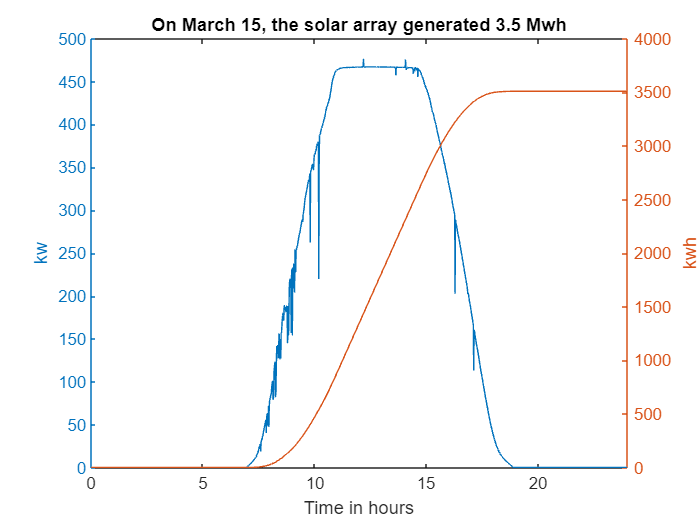

load genData.mat genData
days = string(15:20);
col = days(1);
tot = createEnergyPlot(genData, days, col);
title("Descriptive Title, Please");

% Solution
fmtTitle = "On March %s, the solar array generated %.1f Mwh";
title(compose(fmtTitle,col,tot/1000));

% End Solution

### Slicing up a String

Sometimes there will be a string you want to modify or where you only care about part of the information. 

sentence = "The quick brown fox jumps 3.14' over the lazy dog.";
replaceBetween(sentence,"The","brown"," slow ")

ans = "The slow brown fox jumps 3.14' over the lazy dog."

replace(sentence,"3.14","1.25")

ans = "The quick brown fox jumps 1.25' over the lazy dog."

extractBetween(sentence,"o","o")

ans = 2×1 string array
    "wn f"
    "ver the lazy d"


extractAfter(sentence,"fox")

ans = " jumps 3.14' over the lazy dog."

** Exercise 2**.

Run the following code to generate sentences including a randomly chosen month and day. Write code that will extract the month from `sentence` as a string into the variable `month`. Be sure to get only the name of the month and no extra spaces or punctuation. Test your code by running it repeatedly. 

sentence = generateSentence

sentence = "It is April 19, and all is well."

% % Solution
month = extractBetween(sentence, "is "," ")

month = "April"

% % End Solution

## Further Explorations

Sometimes you may not know exactly what is coming before or after a piece of a string you care about, but you know the general [pattern](https://www.mathworks.com/help/matlab/ref/pattern.html) you are looking for. In this case, you want to describe the pattern and pull out information based on that pattern. Another common term for such pattern matching in code is [regular expressions](https://www.mathworks.com/help/matlab/ref/regexp.html).

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Helper Functions

function str = generateSentence
% generateSentence creates a sentence with a standard structure containing
% a randomly chosen month and day
day = randi(29);
month = randi(12);
months = ["January" "February" "March" "April" "May" "June" ...
    "July" "August" "September" "October" "November" "December"];
str = "It is " + months(month) + " " + day + ", and all is well.";
end

function tot = createEnergyPlot(genData, days, dayChoice)
% createEnergyPlot creates a plot of the generation data and cumulative
% energy generated on dayChoice; it returns the total energy generated
% on dayChoice in kwh

% Compute the total energy generated in kwh as a function of time
tot = cumtrapz(genData(:,days==dayChoice)/60);
% Set up a vector of times
t = 0:1/60:24-1/60;
yyaxis left
plot(t,genData(:,days==dayChoice))
ylabel("kw")
yyaxis right
plot(t,tot)
ylabel("kwh")
xlabel("Time in hours")
xlim([0 24])
tot = tot(end);
end